# Numerical Methods in Engineering

## Part 1: Cholesky Least Squares Estimation

**a) Cholesky factorization is an alternative to LU decompostion which can be applied on symmetric positive definite matrices. A symmetric positive definite matrix**$\mathit{\mathbf{M}}$**must satisfy the following two conditions:**

**     1. The matrix **$\mathit{\mathbf{M}}$**must be symmetric, i.e. **$\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

**     2. The matrix **$\mathit{\mathbf{M}}$** must be positive definite,  i.e.  **${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$** for  all  **$\mathit{\mathbf{x}}\in \Re^{N\times 1}$**, **$\left\|\mathit{\mathbf{x}}\right\|\not= 0$**.**

**If the above two conditons are met then the matrix **$\mathit{\mathbf{M}}$** can be factored as **


$$\mathit{\mathbf{M}}={\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}$$
                 

**where** $\mathit{\mathbf{U}}$ is a $\mathit{\mathbf{N}}\times \mathit{\mathbf{N}}$**the lower upper matrix with real and positive diagonal enteries. The enteries of matrix **$\mathit{\mathbf{U}}$** are given by the following expression **


$$\textbf{U}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{i,i} - u_i(1:i-1)^Tu_i(1:i-1) }    & \text{if  } i =j\\
    \frac{1}{\textbf{U}_{i,i}} \left(\textbf{M}_{i,j} - u_i(1:i-1)^Tu_j(i:i-1) \right)              & \text{if  } i<j\\
0 & \text{Otherwise}
\end{cases}$$


**The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. The code below tests the Cholesky decomposition function named *****CholeskyDecomposition***** provided in the appendix.**

*Note that because the system is well determined, the norm is very small because Cholesky is made to solve well-determined, symmetric, and positive definite matrices. ,*

**The cell below is used to test the algorithm by computing the Frobenius norm of  **${\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}-\mathit{\mathbf{M}}\ldotp$

M = [2 -1 0; -1 2 -1; 0 -1 2];
U = CholeskyDecomposition(M);
Error = norm(U'*U-M);
disp(Error);

   4.4409e-16



disp(U);

    1.4142   -0.7071         0
         0    1.2247   -0.8165
         0         0    1.1547



**b) In regression problems, normal equations such as **${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$** are often solved. The proof below shows that the matrix **$\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$** is symmetric positive definite, and thus can be factored using Cholesky Decomposition.**

- $A^TA$* is symmetric if taking its transpose results in the same matrix: *$(A^TA)^T = A^T(A^T)^T = A^TA$*. Additionally, a symmetric matrix can only be a square matrix.*

- $A^TA$* is positive definite if pre-multiplying and post-multiplying it by the same vector always results in a positive number. First, put the matrix into a quadratic form *$x^TMx$* where *$M=A^TA$*, such that *$x^T(A^TA)x$* is a scalar value. This quadratic form can then be used to test positive definiteness: *$x^TA^TAx = (Ax)^T(Ax) = ||Ax||^2 \gt 0$* because *$A$* is invertible (*$Ax \neq 0$* ). *

**c) Using Cholesky factorization scheme, **${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}$ c**an be factored as **${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;=\;{{\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} }^{\;} \mathit{\mathbf{U}}={\textrm{LL}}^{\mathit{\mathbf{T}}}$**. This transforms the normal equation into the form:**


$${\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


**The above equation consists of the triangular systems in which the solution x can be obtained by first solving **${\mathit{\mathbf{U}}}^T \mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$** using the forward substitution, then by solving the  **$\textrm{Ux}=\mathit{\mathbf{y}}$** using backward subsitution. The Cholesky solver function named *****LeastSquareSolver_Cholesky *****for least squares is implemented in the appendix.**

*The Least Square Cholesky Solver is an approximation and will therefore compute the closest value to the answer. Note that because A is an overdetermined system, computing the norm produces a value with a magnitude of around *$10^{-1}$*. *

**The Cholesky Least Square solver is tested below.**

A = rand(30,15); % random over-determined system
b = ones(30,1);

x = LeastSquareSolver_Cholesky(A, b);

residual = A*x-b;
Norm_residual = norm(residual);

disp(['Question 1c: The norm of the residual after solving using Cholesky based least square solver is '  num2str(Norm_residual)]);

Question 1c: The norm of the residual after solving using Cholesky based least square solver is 0.61516


**Sources used to complete this section:**

- [https://math.emory.edu/~lchen41/teaching/2020_Fall/Section_8-3.pdf](https://math.emory.edu/~lchen41/teaching/2020_Fall/Section_8-3.pdf)

- [https://medium.com/sho-jp/linear-algebra-101-part-8-positive-definite-matrix-4b0b5acb7e9a](https://medium.com/sho-jp/linear-algebra-101-part-8-positive-definite-matrix-4b0b5acb7e9a)

- https://www.youtube.com/watch?app=desktop&v=H7EwHBN9Vus&ab_channel=TheCompleteGuidetoEverything

- [https://www.mathworks.com/help/matlab/math/determine-whether-matrix-is-positive-definite.html](https://www.mathworks.com/help/matlab/math/determine-whether-matrix-is-positive-definite.html)

- [https://www.youtube.com/watch?v=tYpW-PyLGR4&ab_channel=ATTIQIQBAL](https://www.youtube.com/watch?v=tYpW-PyLGR4&ab_channel=ATTIQIQBAL)

- [https://www.mathworks.com/matlabcentral/answers/243481-what-is-the-difference-between-a-vs-a](https://www.mathworks.com/matlabcentral/answers/243481-what-is-the-difference-between-a-vs-a)

- [https://www.mathworks.com/help/matlab/ref/mtimes.html](https://www.mathworks.com/help/matlab/ref/mtimes.html)

- [https://people.math.wisc.edu/~roch/mmids/math535-f20/qr-3-overdetermined.pdf](https://people.math.wisc.edu/~roch/mmids/math535-f20/qr-3-overdetermined.pdf)

- https://cims.nyu.edu/~donev/Teaching/SciComp-Spring2012/Lecture4.handout.pdf

## Part 2: Proofs 

**a) Showing that the condition number of **$A^TA$** is **$\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$**.**

*Condition number for a matrix:*


$$k(A)=\frac{\sigma_1}{\sigma_n}=\frac{min(\sqrt{eig(A^TA)})}{max(\sqrt{eig(A^TA)})}$$


*Substituting *$A$* with *$A^TA$,* the following equivalence can be shown:*


$$k(A^TA)=
\frac
{min(\sqrt{eig((A^TA)^TA^TA)})}
{max(\sqrt{eig((A^TA)^TA^TA)})}$$


*The inner part of the eigenvalue can be simplified:*


$$eig((A^TA)^TA^TA) = eig(A^TAA^TA) = eig((A^TA)^2) = eig(A^TA)^2 $$


*Expanding the square and brining it outside of the equation:*


$$k(A^TA)=
\frac{min(\sqrt{eig(A^TA)^2})}
{max(\sqrt{eig(A^TA)^2})}\\

k(A^TA)=
\frac{min(\sqrt{eig(A^TA)}^2)}
{max(\sqrt{eig(A^TA)}^2)} \\
k(A^TA)=
\left(\frac{min(\sqrt{eig(A^TA)})}
{max(\sqrt{eig(A^TA)})}\right)^2$$



$$k(A^TA)=k(A)^2$$


*The result of *$k(A^TA)$ *is the same as *$k(A)^2$

**b) Given two orthonormal matrices **$U$**and **$Q$**, showing that product of these matrices, **$\textrm{UQ}$**, is also orthonormal.**

*An orthonormal matrix is a square matrix whose columns are all orthogonal unit vectors. A matrix is orthogonal if when multiplied by the transpose, it yields the identity matrix *$I$.* The product of two orthonormal matrices is also orthonormal if multiplying the product of *$UQ$ its transpose produces $I$.


$$(UQ)^T(UQ) = Q^TU^TUQ = Q^TIQ = Q^TQ = I$$


**c) If A is an invertible matrix and Q is an orthonormal matrix, showing that **$\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

*Condition number for a matrix:*


$$k(A)=\frac{\sigma_1}{\sigma_n}=\frac{min(\sqrt{eig(A^TA)})}{max(\sqrt{eig(A^TA)})}$$


*Substituting *$A$* with *$QA$,* the following equivalence can be shown:*


$$k(QA)=\frac{min(\sqrt{eig((QA)^TQA)})}{max(\sqrt{eig((QA)^TQA)})}$$


*The inner part of the eigenvalue can be simplified and *$Q^TQ$ can be illiminated due to orthonormality*:*


$$eig((QA)^TQA) = eig(A^TQ^TQA) = eig(A^TIA) = eig(A^TA) $$



$$k(QA)=\frac{min(\sqrt{eig(A^TA)})}{max(\sqrt{eig(A^TA)})}=k(A)$$


*The result of *$k(QA)$ *is the same as *$k(A)$

**Sources used to complete this section:**

- [https://mailto-surajk.medium.com/a-quick-introduction-to-orthonormal-matrices-15bb54682572](https://mailto-surajk.medium.com/a-quick-introduction-to-orthonormal-matrices-15bb54682572)

- [https://www.youtube.com/watch?v=wGsotn_yS7g&t=590s&ab_channel=EddaMontano](https://www.youtube.com/watch?v=wGsotn_yS7g&t=590s&ab_channel=EddaMontano)

- [https://www.physicsforums.com/threads/proving-that-cond-ata-cond-a-2.446917/](https://www.physicsforums.com/threads/proving-that-cond-ata-cond-a-2.446917/)

- [https://www.youtube.com/watch?v=OG2Wbkd4vgU&ab_channel=MathsResource](https://www.youtube.com/watch?v=OG2Wbkd4vgU&ab_channel=MathsResource)

- https://www.math.uwaterloo.ca/~hwolkowi/matrixcookbook.pdf

## Part 3: QR Decomposition

**In this section, two different algorithms will be used to implment QR Factorization.**

% A 15x6 matrix of random numbers
rng(42); % seed for random generator
test_matrix = rand(15,6); 

% An ill-conditioned matrix to showcase the performance of the two algorithms
size = 200;
ill_conditioned_matrix = 0.00001*eye(size)+Hilbert_matrix(size);

**a) The cell below is used to test a function that computes Gram-Schmidt-based QR decompositon of an input matrix **$A$**. It is verified by computing the Frobenius Norm **${\left\|A-Q\;R\right\|}_F$** in MATLAB. A comment on the results is provided below.**

*The gram-schmidt algorithm evaluates normally on the test_matrix generated from random numbers. This can be seen with a low Frobenius Norm of around *$10^{-16}$*. Furthermore, evaluating the algorithm on an ill-conditioned matrix called ill_conditioned_matrix produces a very high value when calculating the norm of *$Q^TQ - I$*, showcasing how the gschmidt algorithm is numerically unstable.*

[Qgs,Rgs] = gschmidt(test_matrix);
[Q_gs, R_gs] = gschmidt(ill_conditioned_matrix);

% Using the Frobenius Norm to verify correct functionality
normGS = norm(test_matrix-Qgs*Rgs,'fro') ;
disp(normGS);

   3.4889e-16



% Verifying the accuracy of gschmidt
disp(norm(Q_gs'*Q_gs-eye(size), 'fro'));  % Should be large

    0.3140



**b)  The cell below is used to implement a function that uses the Modified Gram-Schmidt approach to compute the QR decompositon of the input matrix A.** **It is verified by computing the Frobenius Norm **${\left\|A-Q\;R\right\|}_F$** in MATLAB. A comment on the results is provided below.**

*The modified-gram-schmidt algorithm evaluates normally on the test_matrix generated from random numbers. This can be seen with a low Frobenius Norm of around *$10^{-16}$*. Furthermore, evaluating the algorithm on an ill-conditioned matrix called ill_conditioned_matrix produces a very small value of *$10^{-11}$* when calculating the norm of *$Q^TQ - I$*. This shows that the mgschmidt algorithm is working correctly and outperforms the gschmidt algorithm. *

[Qmgs,Rmgs] = mgschmidt(test_matrix);
[Q_mgs, R_mgs] = mgschmidt(ill_conditioned_matrix);

% Using the Frobenius Norm to verify correct functionality
normMGS = norm(test_matrix-Qmgs*Rmgs,'fro');
disp(normMGS);

   5.4328e-16



% Verifying accuracy of mgschmidt
disp(norm(Q_mgs'*Q_mgs - eye(size), 'fro'));  % Should be small

   2.3927e-11



**Sources used to complete this section:**

- [https://www.mathworks.com/help/matlab/ref/eye.html](https://www.mathworks.com/help/matlab/ref/eye.html)

- [https://web.mit.edu/18.06/www/Essays/gramschmidtmat.pdf](https://web.mit.edu/18.06/www/Essays/gramschmidtmat.pdf)

- [https://math.stackexchange.com/questions/3913710/intuitive-explanation-of-why-the-modified-gram-schmidt-is-more-stable-than-the-c#:~:text=%22Classical%20Gram%2DSchmidt%2C%20in,get%20at%20the%20end%20of](https://math.stackexchange.com/questions/3913710/intuitive-explanation-of-why-the-modified-gram-schmidt-is-more-stable-than-the-c#:~:text=%22Classical%20Gram%2DSchmidt%2C%20in,get%20at%20the%20end%20of)

- https://math.stackexchange.com/questions/1676345/stable-gram-schmidt/1676362#1676362

## **Part 4: Polynomial Fitting Using Least Squares Estimation **

**Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown below, **

    
$$\matrix{   Input: x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output: y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


**an **$n^{\textrm{th}}$**degree polynomial **$p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$** can be constructed. To find the coefficicients,  **$a=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$**, the linear system shown below can be solved. The system **$\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$** can then be solved to compute the coefficients in vector **$\mathit{\mathbf{a}}\ldotp$


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{Y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


**a) A function called *****PolynomialMatrix***** is written in the appendix. It takes in the input data vector **$\mathit{\mathbf{x}}$** and the degree of the polynomial, returning the polynomial matrix **$\mathit{\mathbf{M}}\ldotp$** The method is tested with X= [1, 2, 3] for degree 3 and verified manually if a polynomial matrix is produced.**

X = [1; 2; 3];
Mtest = PolynomialMatrix(X,3);
disp(Mtest)

     1     1     1     1
     1     2     4     8
     1     3     9    27



% disp(Mtest);

**b) The least squares method can be used to solve the overdetermined linear system **$\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$** to obtain the polynomial coefficients. This can be done by directly solving the Normal equations (using cholesky decomposition for example) or by using QR decomposition. In the code below, MATALB's QR decomposition function is used to find the polynomial coefficients if we assume a polynomial model of order 1. **

load("Polynomial_Fitting_Data.mat");
polynomial_degree = 1;
x = x_given;
y = y_given;

% Polynomial Matrix 
Mp = PolynomialMatrix(x,polynomial_degree);
   
% MATLAB QR Decomposition
[Q,R] = qr(Mp, "econ");

% The polynomial coefficients using Q & R matrices obtained obove
y_sub = Q.'*y;
Ar = backward_sub(R,y_sub);

**After obtaining the coefficients for the first order polynomial model, **$p\left(x\right)=a_0 +a_1 x$**, the model can be tested by evaluating **$p\left(x\right)$** at different values of **$x$** between 0 to 7. The results from the code and the resulting output are explained below. **

*The obtained model from using a 1st degree polynomial significantly underfits the data. Visually observing the trend of the data, it can be seen that the curve is following a sinusoidal pattern and using only a first order polynomial is not enough to create a well-fitted function, even if a lot of data points are used for obtaining the model.*

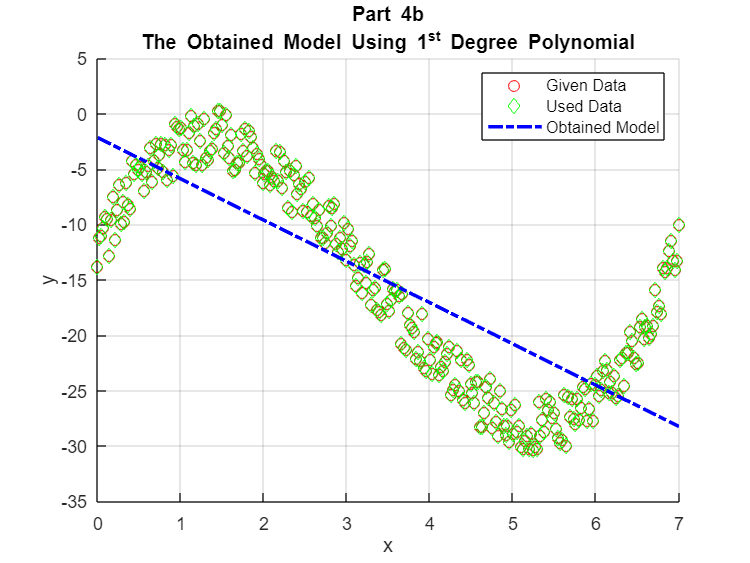

xtest = x;

px = zeros(length(xtest),1);
powers = 0:polynomial_degree;
for I = 1:length(powers)
    px = px + Ar(I)*xtest.^powers(I);   
end

% Plots
figure
hold on
plot(x,y,'ro')
plot(x,y,'gd')
plot(xtest,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend('Given Data','Used Data','Obtained Model')
grid on
title({'Part 4b';'The Obtained Model Using 1^{st} Degree Polynomial'})

**c) In this part, a higher order model (a polynomial of order 6) will be used. Additionally, the number of input data points to generate the model will be limited to only 15. QR decomposition is used to find the polynomial coefficients for the 6th degree polynomial.  **

load('Polynomial_Fitting_Data.mat');
polynomial_degree = 6;
x = x_given(1:15:end);  % x has 15 data points
y = y_given(1:15:end);  % y has 15 data points

% Polynomial Matrix 
Mp= PolynomialMatrix(x, polynomial_degree);


% MATLAB QR Decomposition
[Q,R] = qr(Mp,"econ");

% The polynomial coefficients using Q & R matrices obtained obove
y_sub = Q.'*y;
Ar = backward_sub(R,y_sub);

**The model can be tested by evaluating **$p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$** at different values of **$x$** between 0 to 7. The results from the code and the resulting output are explained below. **

*The obtained model from using 6th degree polynomial does a decently good fiting to the overall curve displayed by the data. However, given the small amount of data points used to create the model (only 15 out of 300), it can be seen that the blue obtained model curve is outlining a slightly different shape compared to the trend seen from all of the other data points. *

*An additional observation is that the obtained model curve is fitting well to the data used (green points) and not as well to the overall given data (red points). It can be concluded that the model is still underfitting to the data with a polynomial of degree 6 and a better fitted curve could be constructed if more data points were used. However, if too many data points are used to fit the curve, then the model would be significantly overfitting and that is not preferred either. Overall, this obtained model using 6th degree polynomial for 15 data points produces the best fitting to the data points.*

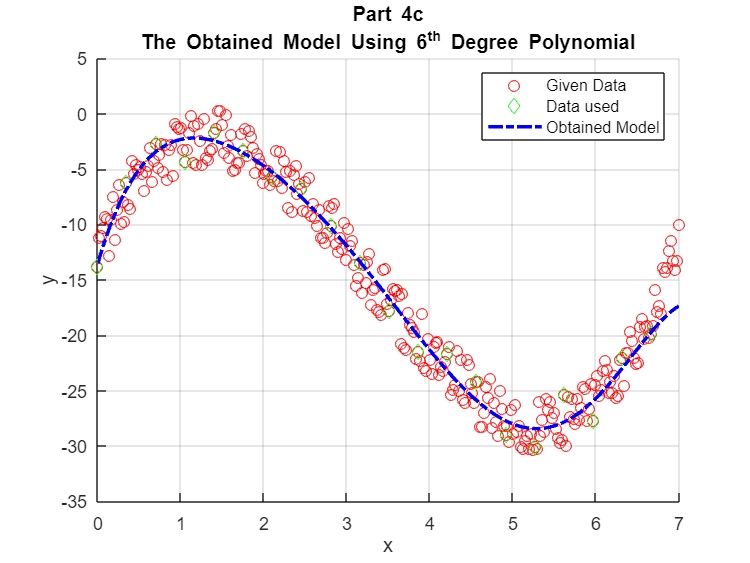

xtest = linspace(0,7,701);
xtest = xtest';
powers = 0:polynomial_degree;
px = zeros(length(xtest),1);

for I = 1:length(powers)
   px = px + Ar(I)*xtest.^powers(I);   
  
end

% Plots
figure
hold on
plot(x_given,y_given,'ro') % plot All Data
plot(x,y,'gd') % plot Used Data
plot(xtest,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend('Given Data','Data used','Obtained Model')
title({'Part 4c';'The Obtained Model Using 6^{th} Degree Polynomial'})
grid on

**d ) This part uses a polynomial of order 14. Additionally, the number of input data points to generate the model will be limited to only 15, like in part c. QR decomposition is used to find the polynomial coefficients for the 14th degree polynomial. ** 

load('Polynomial_Fitting_Data.mat');
polynomial_degree = 14;
x = x_given(1:15:end);  % x has 15 data points 
y = y_given(1:15:end);  % y has 15 data points

% Polynomial Matrix 
Mp= PolynomialMatrix(x, polynomial_degree);


% MATLAB QR Decomposition
[Q,R] = qr(Mp,"econ");

% The polynomial coefficients using Q & R matrices obtained obove
y_sub = Q.'*y;
Ar = backward_sub(R,y_sub); 

**The model can be tested by evaluating **$p\left(x\right)$** at different values of **$x$** between 0 to 7. Is this a good model? The results from the code and the resulting output are explained below. **

*The obtained model from using 14th degree polynomial does a poor fitting to the overall curve displayed by the data. Upon closely inspecting the obtained model (blue curve), it can be seen that it passes through all the green points (data used) and does not reflect the sinusoidal nature of the total data. This shows that the obtained model is overfitting to the small amount of data used and does not show the overall pattern of the given data. Overall, the obtained model using a 14th degree polynomial for 15 data points produces a poorly fitted model and signifies that a polynomial of order 14 is too high to fit the provided data. *

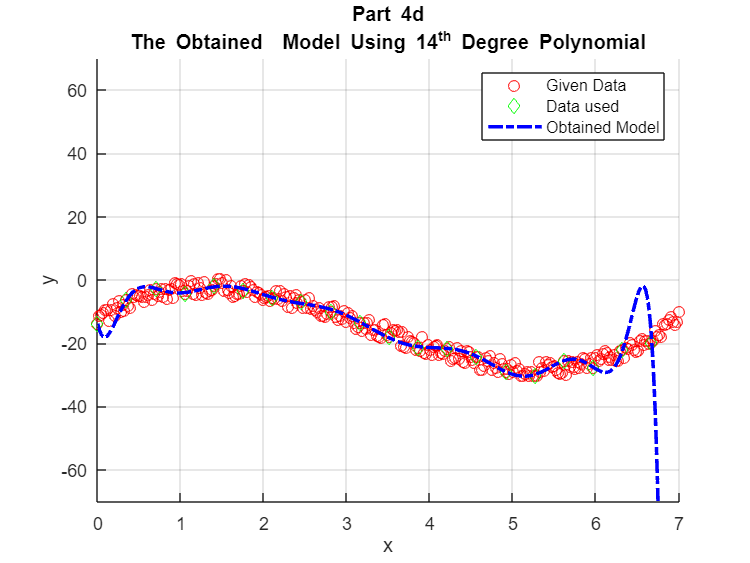

xtest = linspace(0,7,701);
xtest = xtest';
powers = 0:polynomial_degree;
px = zeros(length(xtest),1);

for I = 1:length(powers)
   px = px + Ar(I)*xtest.^powers(I);   
end

% Plots
figure('Name','Part 4d','NumberTitle','off')
hold on
plot(x_given,y_given,'ro') % plot All Data
plot(x,y,'gd') % plot Used Data
plot(xtest,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
ylim([-70 70])
legend('Given Data','Data used','Obtained Model')
title({'Part 4d';'The Obtained  Model Using 14^{th} Degree Polynomial'})
grid on

**Sources used to complete this section:**

- [https://www.youtube.com/watch?v=TZAtc06QkmM&ab_channel=NickSpaceCowboy](https://www.youtube.com/watch?v=TZAtc06QkmM&ab_channel=NickSpaceCowboy)

- https://en.wikipedia.org/wiki/Polynomial_matrix#:~:text=In%20mathematics%2C%20a%20polynomial%20matrix,polynomial%20whose%20coefficients%20are%20matrices.

## Appendix 

## *Cholesky Decomposition*

function U = CholeskyDecomposition(M)
    if (size(M,1) ~= size(M,2))
        disp('Matrix M must be square!');
        return;
    end

    if ~issymmetric(M)
        disp('Matrix M must be symmetric!');
        U = [];
        return;
    end

    % Check for positive definiteness (all eigenvalues must be positive)
    if any(eig(M) <= 0)
        disp('Matrix M must be positive definite!');
        U = [];
        return;
    end

    % Algorithm
    n = size(M, 1);
    U = zeros(n);

    for i = 1:n
        for j = i:n
            if i == j
                % Compute the diagonal element
                U(i, i) = sqrt(M(i, i) - U(1:i-1, i).' * U(1:i-1, i));
            elseif i < j
                % Compute the off-diagonal element
                U(i, j) = (M(i, j) - U(1:i-1, i).' * U(1:i-1, j)) / U(i, i);
            end
        end
    end
end

## *Least Square Solver for Cholesky*

function x = LeastSquareSolver_Cholesky(A,b)
    M = A.'*A; % M = A^TA

    % Step 1. Calling the Cholesky function to get the lower triangular matrix L
    U = CholeskyDecomposition(M); % M = LL^T = U^TU
    L = U.'; 
    
    % Step 2. Using the forward substitution function to solve for y in LUx = A^Tb to get Ly = A^Tb
    y = forward_sub(L, (A.'*b));

    % Step 3. Using the backward substitution function to solve for x in Ux = y
    x = backward_sub(U, y);
end

## *Polynomial Matrix*

function M = PolynomialMatrix(x,n)
    % x is the vector of input data
    % n is the degree of the polynomial
    [rows, ~] = size(x);
    M = ones(rows, n+1);
    
    for p = 1:n
        M(:,p+1) = M(:,p).*x;
    end
end

## *QR Decomposition Methods*

- *Classical GramSchmidt*

function [Q,R] = gschmidt(A)
   % A is the input matrix - A could be a overdetermined matrix or a square matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 

   [numRow, numCol] = size(A);
   Q = zeros(numRow,numCol);
   R = zeros(numCol,numCol);
   R(1,1) = norm(A(:,1));
   Q(:,1) = A(:,1) ./ R(1,1);
    for j = 2:numCol
        p = zeros(numRow,1);
        for i = 1:(j-1)
            R(i,j) = Q(:,i)' * A(:,j);
            p = p + R(i,j) .* Q(:,i);
        end
        v = A(:,j) - p;
        R(j,j) = norm(v);
        Q(:,j) = v ./ R(j,j);
    end
end

- *Modified Gram-Schimdt*

function [Q,R] = mgschmidt(A)
    % A is the input matrix - A could be a overdetermined matrix or a square matrix
    % Q is orthonormal matrix 
    % R is the upper trianlgular matrix

    [~, numCol] = size(A);
    Q = A;
    R = zeros(numCol,numCol);

    for i = 1:numCol
        R(i,i) = norm(Q(:,i));
        Q(:,i) = Q(:,i) ./ R(i,i);
        for j = (i + 1):numCol
            R(i,j) = Q(:,i)' * Q(:,j);
            Q(:,j) = Q(:,j) - R(i,j) .* Q(:,i); 
        end
    end
end 

## *Function to Generate a Hilbert Matrix*

function A = Hilbert_matrix(size)
    A = zeros(size,size);
    
    for i=1:size
        for j=1:size
            A(i,j) = 1/(i+j-1);
        end 
    end 
end

## *Helper Functions*

function y = forward_sub(L,b)
    % y is the vector
    % L is the lower triangular matrix
    n = length(b);
    [~, numCol] = size(L);
    y = zeros(n, 1);

    for i = 1:numCol
        if L(i, i) == 0
            error('Division by zero');
        end
        y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
    end
end 

function X = backward_sub(U,y)
    % X is the vector
    % U is the upper triangular matrix
    [numRow, numCol] = size(U);
    X = zeros(numRow, 1);
    y = y(1:numRow);

    for i = numCol:-1:1
        if U(i, i) == 0
            error('Division by zero');
        end
        X(i) = (y(i) - U(i, i+1:numRow) * X(i+1:numRow)) / U(i, i);
    end
end 